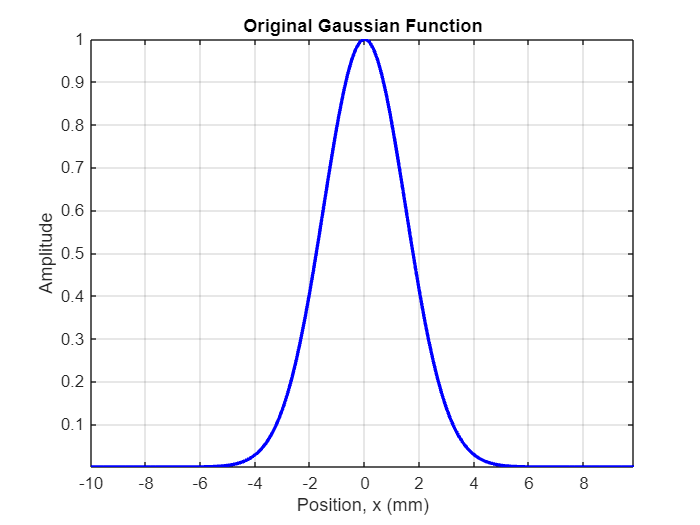

% LAB 3
% DFT Part 2
% Mohanbabu Mani

% 1.

% Taking the 1D DFT of this function transforms it from the spatial domain to 
% the spatial frequency domain. Because the original Gaussian is a real and even function, 
% the real part of its DFT is also a Gaussian-shaped curve.

% When we take the DFT of this new function, we again get a Gaussian-shaped result in the frequency domain. 
% However, because the input array was longer, the output also has more points. 
% The spacing between frequency samples is finer, resulting in a much smoother-looking plot.

% Zero-padding in the spatial domain results in interpolation in the frequency domain.

N = 128;              
L = 20;               
dx = L / N;          
x = (-L/2 : dx : L/2 - dx); 
sigma = 1.5;          
gaussian = exp(-x.^2 / (2 * sigma^2)); 

plot(x, gaussian, 'b-', 'LineWidth', 2);
title('Original Gaussian Function');
xlabel('Position, x (mm)');
ylabel('Amplitude');
grid on;
axis tight;

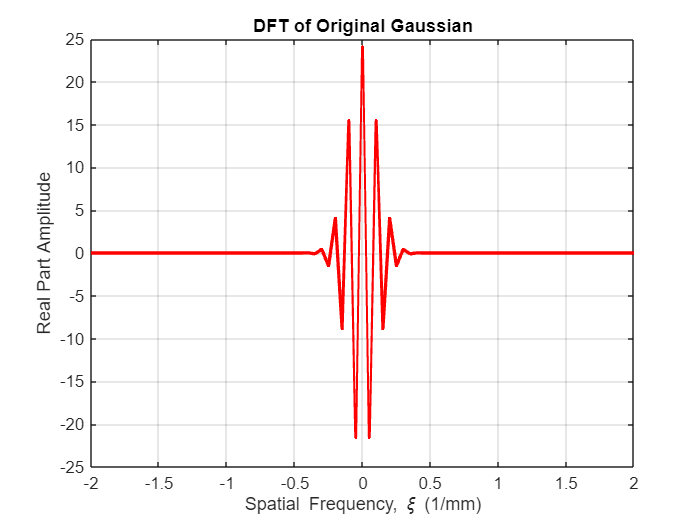


dft_gaussian = fft(gaussian);
fs = 1 / dx; 
xi = (-fs/2 : fs/N : fs/2 - fs/N); 
dft_gaussian_shifted = fftshift(dft_gaussian);

plot(xi, real(dft_gaussian_shifted), 'r-', 'LineWidth', 2);
title('DFT of Original Gaussian');
xlabel('Spatial Frequency, \xi (1/mm)');
ylabel('Real Part Amplitude');
grid on;
xlim([-2, 2]); 

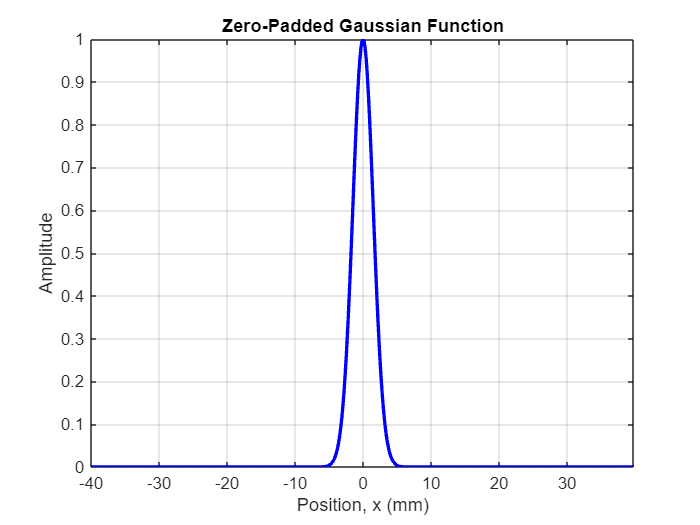


N_pad = 4 * N;
gaussian_padded = zeros(1, N_pad);
start_index = (N_pad - N)/2 + 1;
end_index = start_index + N - 1;
gaussian_padded(start_index:end_index) = gaussian;
L_pad = N_pad * dx;
x_padded = (-L_pad/2 : dx : L_pad/2 - dx);


plot(x_padded, gaussian_padded, 'b-', 'LineWidth', 2);
title('Zero-Padded Gaussian Function');
xlabel('Position, x (mm)');
ylabel('Amplitude');
grid on;
axis tight;

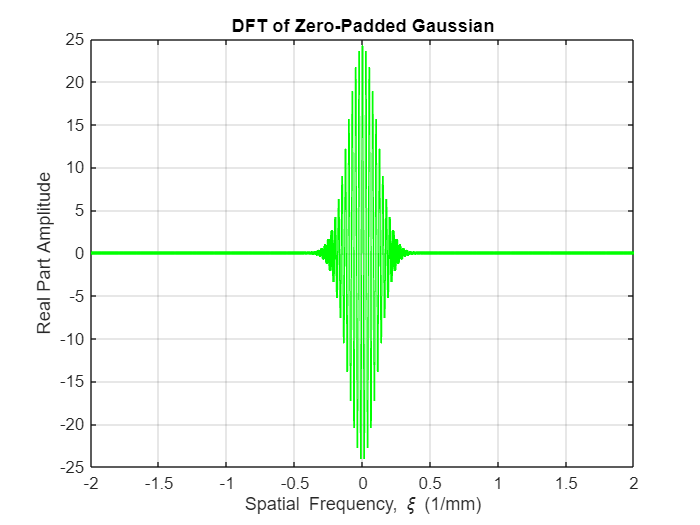


dft_padded = fft(gaussian_padded);
xi_padded = (-fs/2 : fs/N_pad : fs/2 - fs/N_pad);
dft_padded_shifted = fftshift(dft_padded);

plot(xi_padded, real(dft_padded_shifted), 'g-', 'LineWidth', 2);
title('DFT of Zero-Padded Gaussian');
xlabel('Spatial Frequency, \xi (1/mm)');
ylabel('Real Part Amplitude');
grid on;
xlim([-2, 2]);

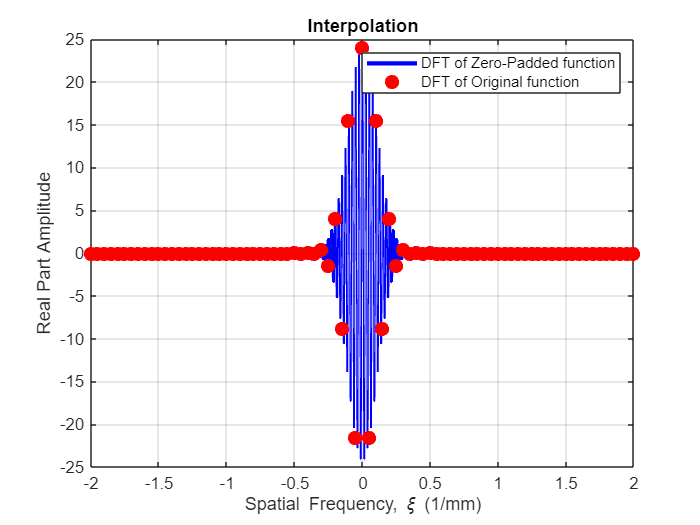


plot(xi_padded, real(dft_padded_shifted), 'b-', 'LineWidth', 2.5, 'DisplayName', 'DFT of Zero-Padded function');
hold on;
plot(xi, real(dft_gaussian_shifted), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8, 'DisplayName', 'DFT of Original function');
hold off; 

title('Interpolation');
xlabel('Spatial Frequency, \xi (1/mm)');
ylabel('Real Part Amplitude');
legend('show');
grid on;
xlim([-2, 2]);

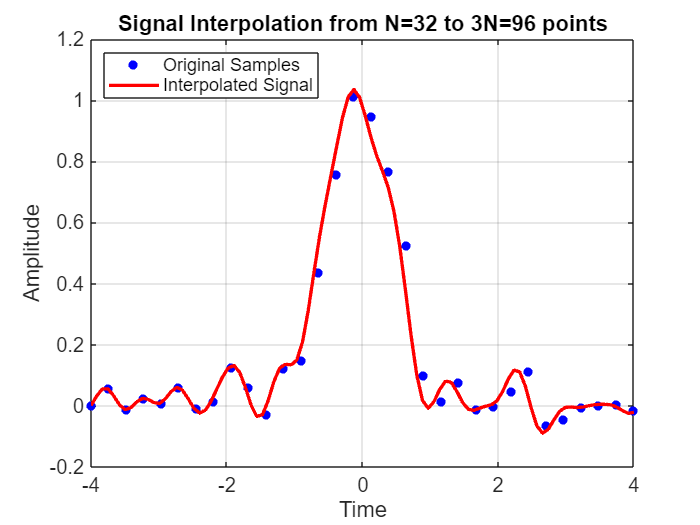

% 2.

% To interpolate in the spatial or time domain, we need zero-pad in the frequency domain. 
% Specifically, the zeros are added to the middle of the frequency spectrum, 
% which corresponds to inserting zero-amplitude, high-frequency components. 
% An inverse DFT then transforms this padded spectrum back into a smoothly
% interpolated spatial signal.


function y_interp = interpolate_dft(x)

    if isrow(x)
        x = x.';
    end

    N = length(x);
    M = 3 * N; 
    X = fft(x);
    split_point = ceil((N + 1) / 2);
    X_first_half = X(1:split_point);
    X_second_half = X(split_point + 1:end);
    Y = [X_first_half; zeros(2 * N, 1); X_second_half];
    interpolation_factor = M / N;
    y_interp = ifft(Y) * interpolation_factor;

    if isreal(x)
        y_interp = real(y_interp);
    end
end

N = 32; 
t_original = linspace(-4, 4, N)'; 
x_original = exp(-2 * t_original.^2); 
x_original = x_original + 0.05 * randn(N, 1); 
y_interpolated = interpolate_dft(x_original);
M = length(y_interpolated); 
t_interpolated = linspace(-4, 4, M)';


plot(t_original, x_original, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 5, 'LineStyle', 'none', 'DisplayName', 'Original Samples');
hold on;
plot(t_interpolated, y_interpolated, 'r-', 'LineWidth', 2, 'DisplayName', 'Interpolated Signal');
hold off;
title(['Signal Interpolation from N=' num2str(N) ' to 3N=' num2str(M) ' points']);
xlabel('Time');
ylabel('Amplitude');
legend('Location', 'northwest');
grid on;
box on;
set(gca, 'FontSize', 12);

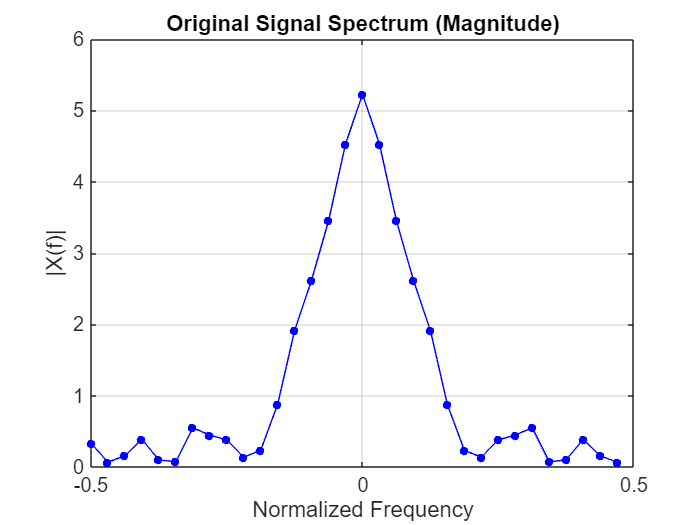


X_original_spec = fft(x_original);
Y_interpolated_spec = fft(y_interpolated);
f_original_axis = (-N/2 : N/2-1) / N;
f_interpolated_axis = (-M/2 : M/2-1) / M;

plot(f_original_axis, abs(fftshift(X_original_spec)), 'b.-', 'MarkerSize', 15);
title('Original Signal Spectrum (Magnitude)');
ylabel('|X(f)|');
xlabel('Normalized Frequency');
grid on;
box on;
set(gca, 'FontSize', 12);

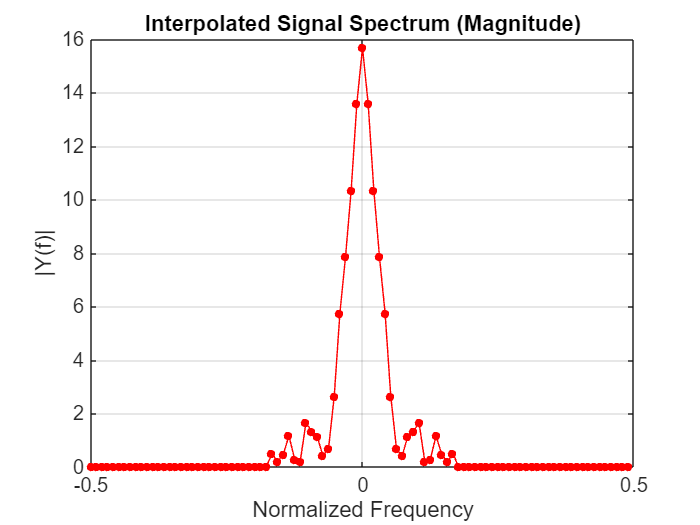


plot(f_interpolated_axis, abs(fftshift(Y_interpolated_spec)), 'r.-', 'MarkerSize', 15);
title('Interpolated Signal Spectrum (Magnitude)');
ylabel('|Y(f)|');
xlabel('Normalized Frequency');
grid on;
box on;
set(gca, 'FontSize', 12);

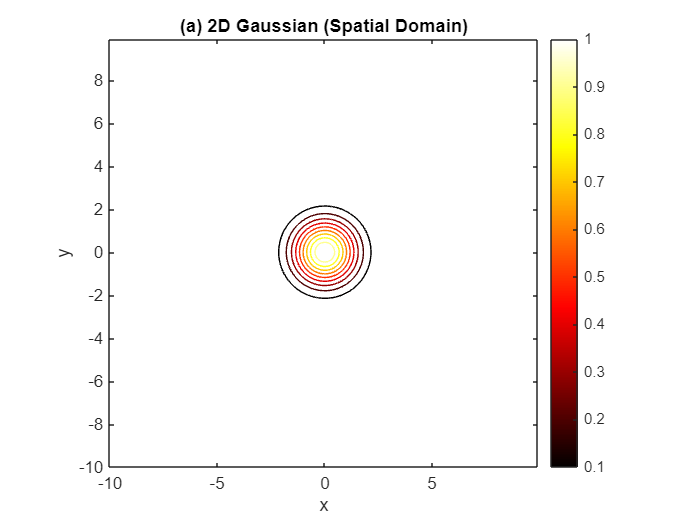

% 3.

% The 2D DFT of a Gaussian function is another 2D Gaussian.
% A wide Gaussian in the spatial domain becomes a narrow Gaussian in the frequency domain.
% The 2D DFT of a square is a 2D Sinc function.
% The 2D DFT of a 2D Sinc function is a 2D Rect function. 
% The result is a sharp, bright square in the center of the frequency domain plot.


N = 256;
L = 20;  
dx = L / N; 
x = (-L/2 : dx : L/2 - dx);
[X, Y] = meshgrid(x, x);
sigma = 1.0; 
gaussian_2d = exp(-(X.^2 + Y.^2) / (2 * sigma^2));
dft_gaussian = fft2(gaussian_2d);
dft_gaussian_disp = log(1 + abs(fftshift(dft_gaussian)));

contour(x, x, gaussian_2d);
title('(a) 2D Gaussian (Spatial Domain)');
xlabel('x'); ylabel('y');
axis square; colormap('hot');
colorbar;

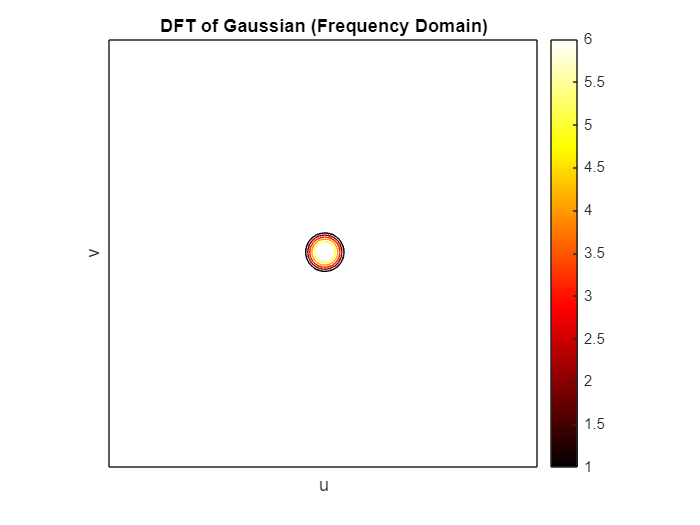


contour(dft_gaussian_disp);
title('DFT of Gaussian (Frequency Domain)');
xlabel('u'); ylabel('v');
axis square; colormap('hot');
xticks([]); yticks([]);
colorbar;

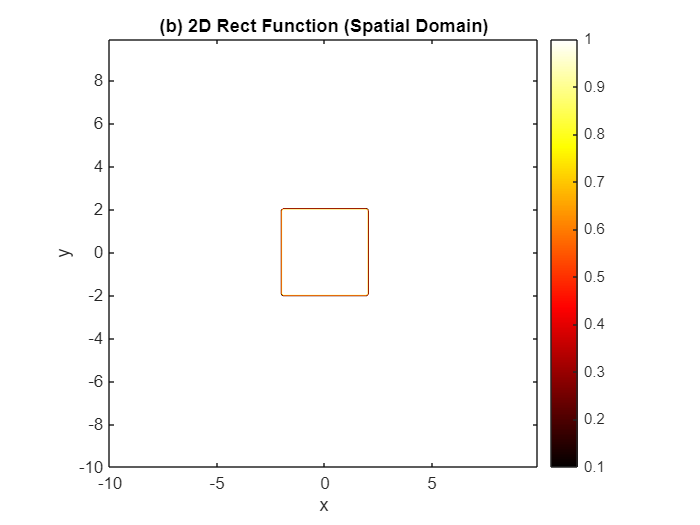


W = 4; 
rect_2d = zeros(N, N);
rect_2d(abs(X) < W/2 & abs(Y) < W/2) = 1;
dft_rect = fft2(rect_2d);
dft_rect_disp = log(1 + abs(fftshift(dft_rect)));

contour(x, x, rect_2d);
title('(b) 2D Rect Function (Spatial Domain)');
xlabel('x'); ylabel('y');
axis square; colormap('hot');
colorbar;

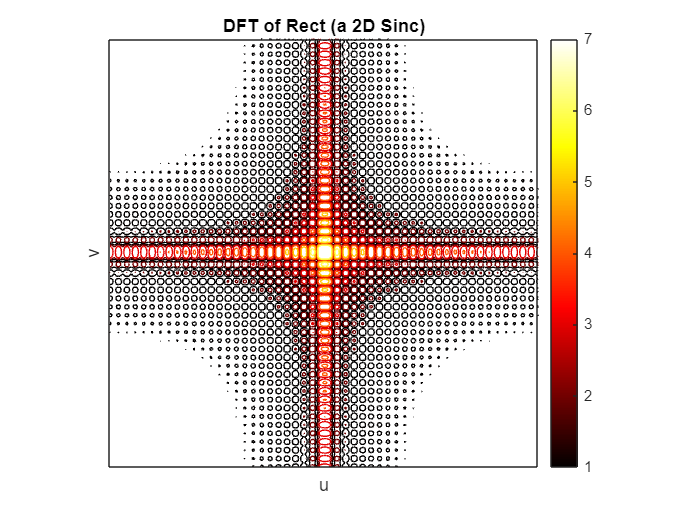


contour(dft_rect_disp);
title('DFT of Rect (a 2D Sinc)');
xlabel('u'); ylabel('v');
axis square; colormap('hot');
xticks([]); yticks([]);
colorbar;

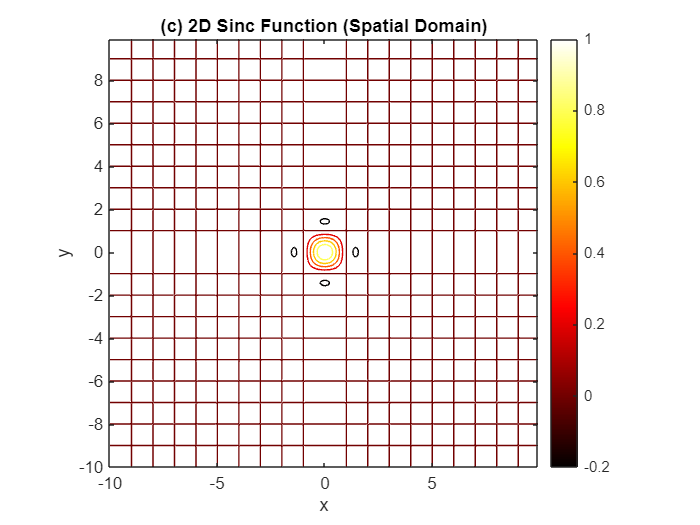


sinc_2d = sinc(X) .* sinc(Y);
dft_sinc = fft2(sinc_2d);
dft_sinc_disp = log(1 + abs(fftshift(dft_sinc)));

contour(x, x, sinc_2d);
title('(c) 2D Sinc Function (Spatial Domain)');
xlabel('x'); ylabel('y');
axis square; colormap('hot');
colorbar;

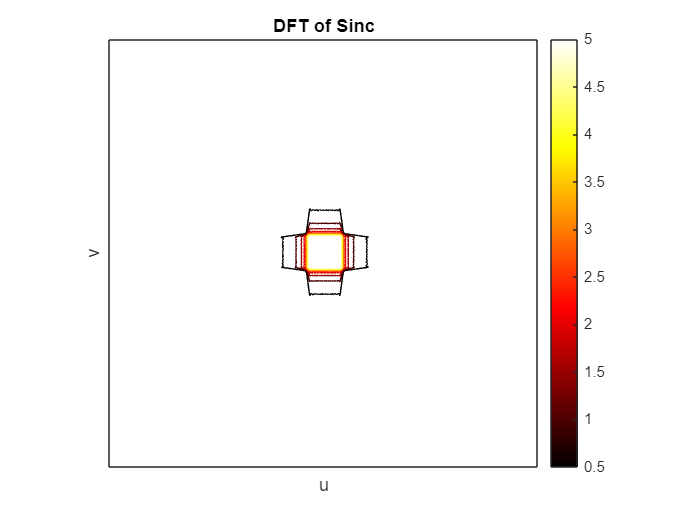


contour(dft_sinc_disp);
title('DFT of Sinc');
xlabel('u'); ylabel('v');
axis square; colormap('hot');
xticks([]); yticks([]);
colorbar;

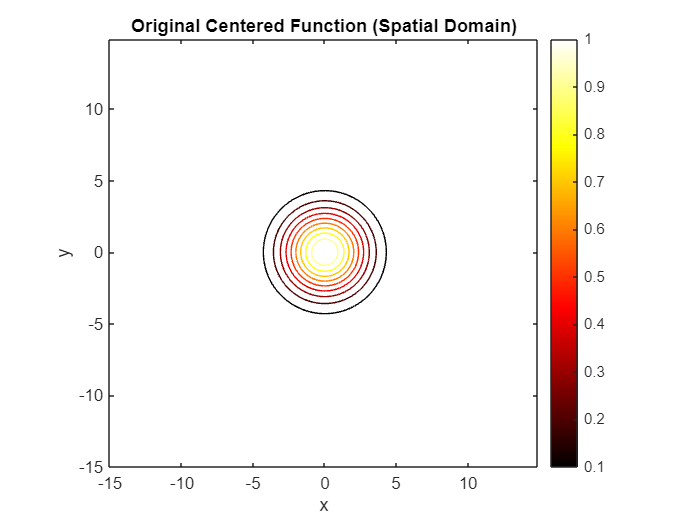

% 4.

% Shifting a function in the spatial domain does not change the magnitude of its Fourier transform, 
% but it does add a linear phase to it.
% Shifting the function spatially does not alter the frequency amplitudes present in the signal.

% The phase of the centered function is essentially zero

N = 256;
L = 30; 
dx = L / N; 
x = (-L/2 : dx : L/2 - dx);
[X, Y] = meshgrid(x, x);

delta_x = 5; 
delta_y = 3;  
sigma = 2.0;
gaussian_centered = exp(-(X.^2 + Y.^2) / (2 * sigma^2));
dft_centered = fftshift(fft2(gaussian_centered));
mag_centered = abs(dft_centered);
phase_centered = angle(dft_centered);

contour(x, x, gaussian_centered);
title('Original Centered Function (Spatial Domain)');
xlabel('x'); ylabel('y');
axis square; colormap(gca, 'hot');
colorbar;

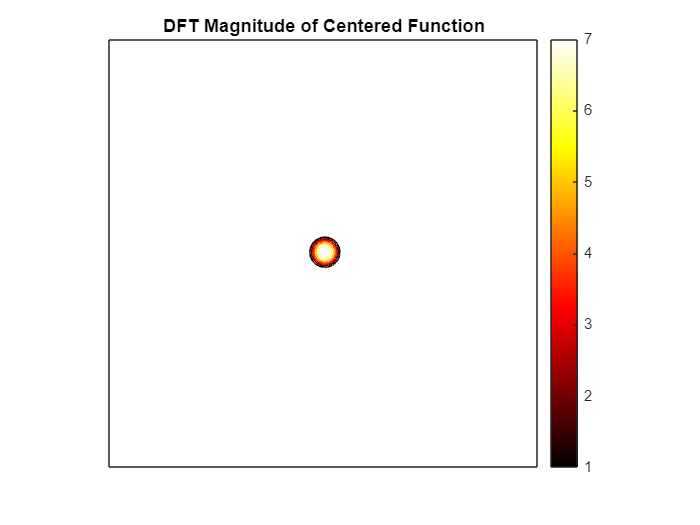


contour(log(1 + mag_centered));
title('DFT Magnitude of Centered Function');
axis square; colormap(gca, 'hot');
xticks([]); yticks([]);
colorbar;

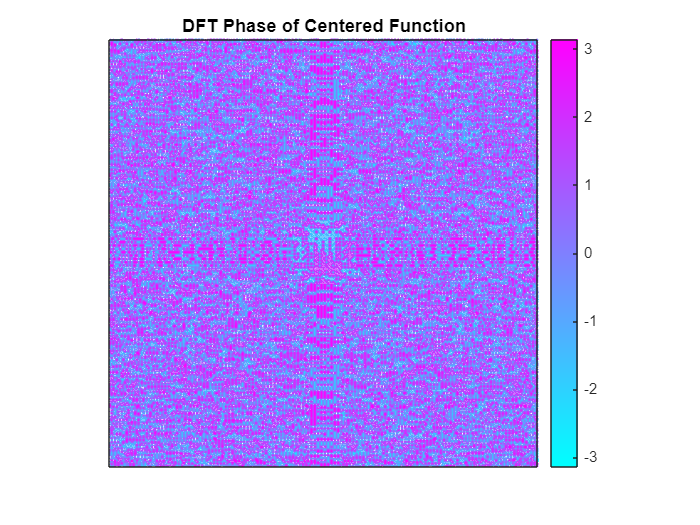


contour(phase_centered);
title('DFT Phase of Centered Function');
axis square; colormap(gca, 'cool');
xticks([]); yticks([]);
caxis([-pi pi]);
colorbar;

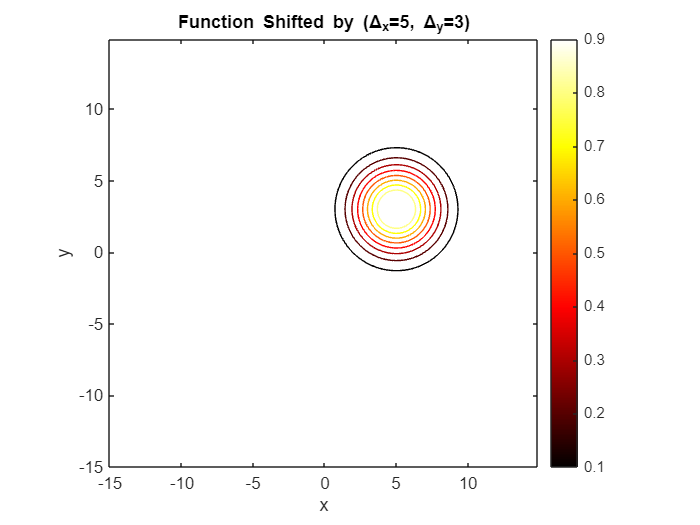


gaussian_shifted = exp(-((X - delta_x).^2 + (Y - delta_y).^2) / (2 * sigma^2));
dft_shifted = fftshift(fft2(gaussian_shifted));
mag_shifted = abs(dft_shifted);
phase_shifted = angle(dft_shifted);

contour(x, x, gaussian_shifted);
title(['Function Shifted by (\Delta_x=', num2str(delta_x), ', \Delta_y=', num2str(delta_y), ')']);
xlabel('x'); ylabel('y');
axis square; colormap(gca, 'hot');
colorbar;

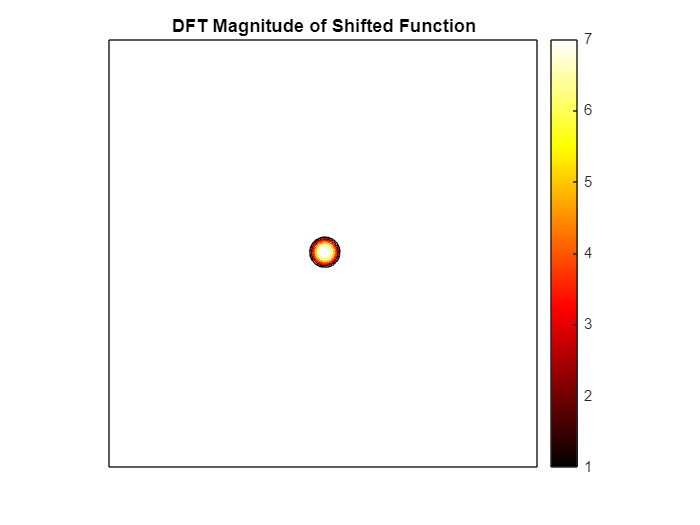


contour(log(1 + mag_shifted));
title('DFT Magnitude of Shifted Function');
axis square; colormap(gca, 'hot');
xticks([]); yticks([]);
colorbar;

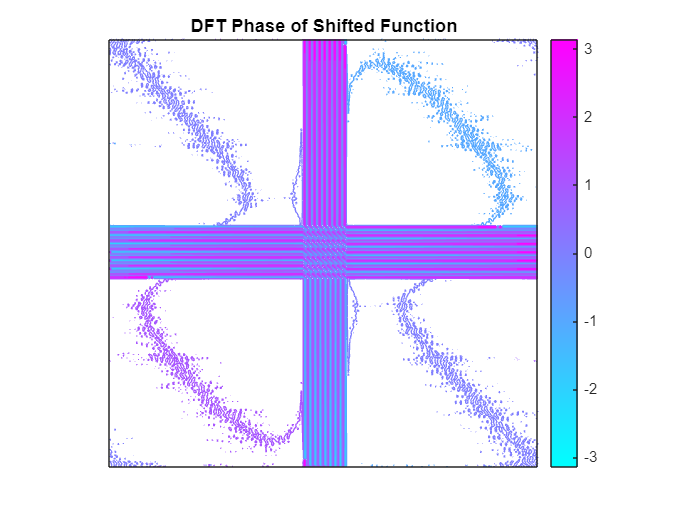


contour(phase_shifted);
title('DFT Phase of Shifted Function');
axis square; colormap(gca, 'cool');
xticks([]); yticks([]);
caxis([-pi pi]); 
colorbar;

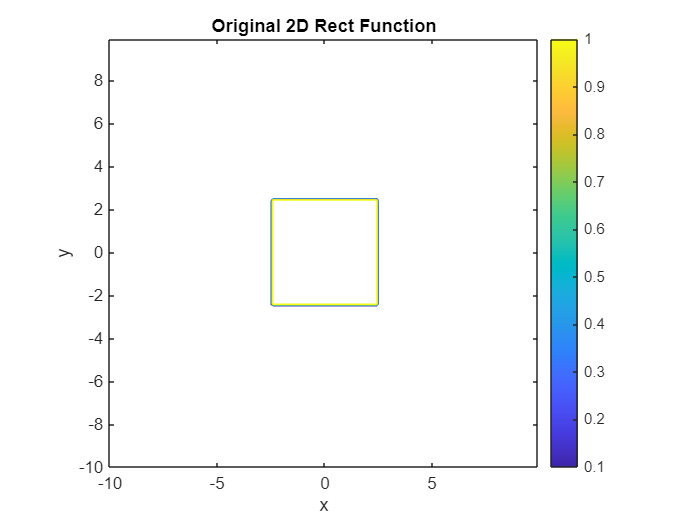

% 5.

% 'dft_result' transforms the intermediate data vertically. 
% It takes the matrix from the first step and processes each of its columns with a 1D fft.
% The final dft_result is the 2D DFT of the original function. 
% The resulting plot shows a 2D Sinc function, which is the correct transform for a 2D Rect function.

N = 256;
L = 20; 
dx = L / N; 

x = (-L/2 : dx : L/2 - dx);
[X, Y] = meshgrid(x, x);
W = 5; 
test_function = zeros(N, N);
test_function(abs(X) < W/2 & abs(Y) < W/2) = 1;

intermediate_matrix = fft(test_function, [], 2);

dft_result = fft(intermediate_matrix, [], 1);

contour(x, x, test_function);
title('Original 2D Rect Function');
xlabel('x'); ylabel('y');
axis square; colormap('parula');
colorbar;

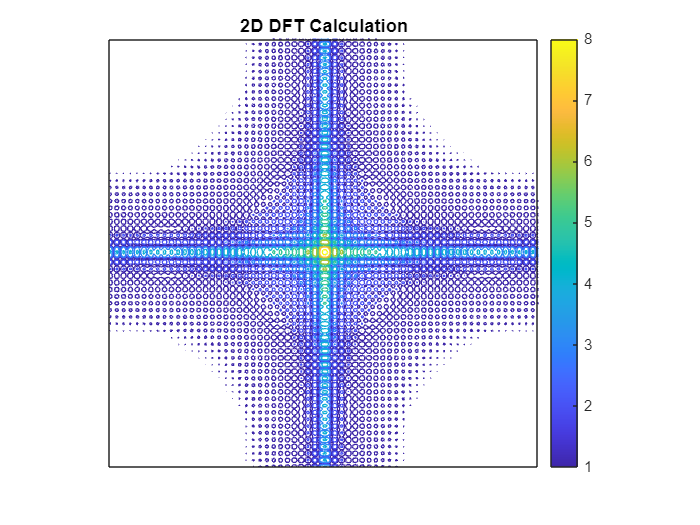


contour(log(1 + abs(fftshift(dft_result))));
title('2D DFT Calculation');
axis square; colormap('parula');
xticks([]); yticks([]);
colorbar;

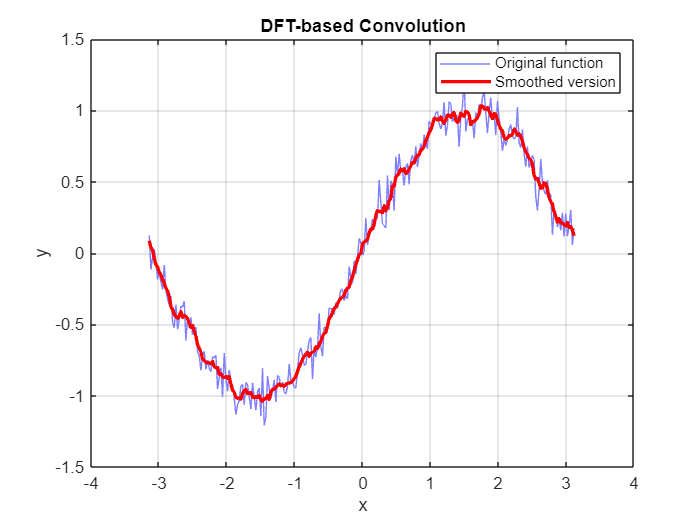

% 6.

% The final plot shows the original noisy sine wave in a light blue 
% and the smoothed version as a thick red line. The smoothed line follows the general shape of the sine wave 
% while averaging out the rapid, high-frequency fluctuations of the random noise. 
% This is the expected result of convolving or performing a moving average on a noisy signal. 

N = 256;
x = linspace(-pi, pi, N + 1);
x = x(1:N);
y = sin(x) + randn(size(x)) * 0.1;

rect_kernel = zeros(size(x));
width = 7;
rect_kernel(1 : ceil(width/2)) = 1;
rect_kernel(end - floor(width/2) + 2 : end) = 1;
rect_kernel = rect_kernel / sum(rect_kernel);

dft_y = fft(y);
dft_rect = fft(rect_kernel);
dft_smoothed = dft_y .* dft_rect;
y_smoothed = ifft(dft_smoothed);
y_smoothed = real(y_smoothed);

figure('Name', 'Smoothing with DFT Convolution');
hold on; 
plot(x, y, 'Color', [0.5 0.5 1.0], 'DisplayName', 'Original function');
plot(x, y_smoothed, 'r-', 'LineWidth', 2, 'DisplayName', 'Smoothed version');

hold off;

title('DFT-based Convolution');
xlabel('x');
ylabel('y');
legend('show');
grid on;
box on;